
clear
close all

etc_wy =   readmatrix('CVavgYly_etc_wy_by_DAU'); % mm
pr_wy =    readmatrix('CVavgYly_pr_wy_by_DAU'); % mm
rmin_wy =  readmatrix('CVavgYly_rmin_wy_by_DAU'); % %
rmax_wy =  readmatrix('CVavgYly_rmax_wy_by_DAU'); % %
tmean_wy = readmatrix('CVavgYly_tmean_wy_by_DAU'); tmean_wy = tmean_wy-273.15; % Celcius
vpd_wy =   readmatrix('CVavgYly_vpd_wy_by_DAU'); % kPa
wy = 1980:2022; % water-years


etc_diff = mean(etc_wy(:,33:43)) - mean(etc_wy(:,1:32));
pr_diff = mean(pr_wy(:,33:43)) - mean(pr_wy(:,1:32));
vpd_diff = mean(vpd_wy(:,33:43)) - mean(vpd_wy(:,1:32));

## Figure 1

Normalized time series

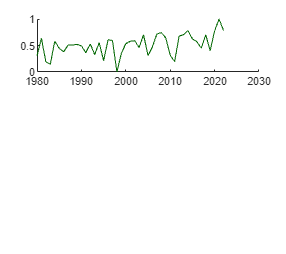

hFig=figure;
set(gcf,'Units','centimeters','position',[25 12 18 16]);
subplot(3,1,1)
hold on
plot(wy,normalize(etc_wy),'Color',[0 0.4 0])

plot(wy,normalize(vpd_wy),'m')

Error using plot
Vectors must be the same length.

text(1985,0.8,'(a)')
ylabel('Normalized Data')
legend('Normalized ET_c','Normalized VPD','Location','eastoutside')
%legend('boxoff');
xtickangle(45)
xticks(1982:4:2022)
xlim([1980 2022])
ylim([0 1])
set(gca,'fontname','helvetica','fontsize',11)
set(gca,'TickDir','out')
hold off

subplot(3,1,2)
%set(gcf,'Units','centimeters','position',[25 12 18 9],'defaultAxesColorOrder',[[0 0 0];[0 0 0]]);
hold on
plot(wy,normalize(rmin_wy./rmax_wy),'Color','b')
text(1985,0.9,'(b)')
ylabel('Normalized r_{min}/r_{max}')
legend('Norm. r_{min}/r_{max}','Location','eastoutside')
xtickangle(45)
xticks(1982:4:2022)
xlim([1980 2022])
ylim([0 1])
set(gca,'fontname','helvetica','fontsize',11)
set(gca,'TickDir','out')
hold off

subplot(3,1,3)
%set(gcf,'Units','centimeters','position',[25 12 18 9],'defaultAxesColorOrder',[[0 0 0];[0 0 0]]);
hold on
plot(wy,normalize(tmean_wy),'r')
text(1985,0.8,'(c)')
ylabel('Normalized T_{air}')
legend('Normalized T_{air}','Location','eastoutside')
xtickangle(45)
xticks(1982:4:2022)
xlim([1980 2022])
ylim([0 1])
set(gca,'fontname','helvetica','fontsize',11)
set(gca,'TickDir','out')
hold off
% 
% f = gcf; 
% exportgraphics(f,'normalized_timeseries_data.png','Resolution',500)
% exportgraphics(f,'figure1.png','Resolution',500)


subplot(3,1,1)
xlim([1980.0 2022.0])
ylim([0.00 1.00])

## Figure 1 version 2

Non-normalized time series

hFig=figure;
set(gcf,'Units','centimeters','position',[25 12 18 12]);
subplot(2,1,1)
plot(wy,etc_wy,'Color',[0 0.4 0])
text(1985,1100,'(a)')
ylabel('ET_c (mm)')
xtickangle(45)
xticks(1982:4:2022)
xlim([1980 2022])
ylim([900 1150])
set(gca,'fontname','helvetica','fontsize',11)
set(gca,'TickDir','out')
subplot(2,1,2)
plot(wy,vpd_wy,'m')
text(1985,1.8,'(b)')
ylabel('VPD (kPa)')
xtickangle(45)
xticks(1982:4:2022)
yticks(1:0.2:2)
xlim([1980 2022])
set(gca,'fontname','helvetica','fontsize',11)
set(gca,'TickDir','out')
hold off

f = gcf; 
exportgraphics(f,'timeseries_data2.png','Resolution',500)
exportgraphics(f,'Figure 2 final.png','Resolution',500)
exportgraphics(f,'Figure 2 final.eps','Resolution',500)

## Table 1

Wilcoxon rank sum test

[p1,h1,stats1] = ranksum(etc_wy(1:32), etc_wy(33:43));
[p2,h2,stats2] = ranksum(pr_wy(1:32),  pr_wy(33:43));
[p3,h3,stats3] = ranksum(vpd_wy(1:32), vpd_wy(33:43));

## Figure 2

ETc and P bar charts

figure
set(gcf,'Units','centimeters','position',[25 12 18 16]);
subplot(2,1,1)
hold on
bar(wy,pr_wy,'FaceColor',[0.30,0.75,0.93],'EdgeColor',[0.30,0.75,0.93],'FaceAlpha',0.8,'EdgeAlpha',0.8)
plot([1980,2022],[262,262],'k--','LineWidth',1)
ylabel('P (mm)')
ylim([0 1200])
text(1985,1150,'(a)')
xtickangle(45)
xlim([1979.5 2022.5])
set(gca,'fontname','helvetica','fontsize',11)
set(gca,'TickDir','out')
xticks(1982:4:2022)
legend('   P','   P Baseline','Location','eastoutside')

subplot(2,1,2)
hold on
bar(wy,etc_wy,'FaceColor',[0.47 0.67 0.19],'EdgeColor',[0.47 0.67 0.19],'FaceAlpha',0.8,'EdgeAlpha',0.8)
plot([1980,2022],[1014,1014],'k--','LineWidth',1)
ylabel('ET_c (mm)')
ylim([0 1200])
text(1985,1150,'(b)')
xtickangle(45)
xlim([1979.5 2022.5])
set(gca,'fontname','helvetica','fontsize',11)
set(gca,'TickDir','out')
xticks(1982:4:2022)
legend('ET_c','ET_c Baseline','Location','eastoutside')
f = gcf; 
exportgraphics(f,'barcharts_timeseries_data.png','Resolution',500)
exportgraphics(f,'Figure 3 final.png','Resolution',500)
exportgraphics(f,'Figure 3 final.eps','Resolution',500)

## Figure 3

figure
set(gcf,'Units','centimeters','position',[25 12 12 12]);
hold on
x1 = pr_wy(:,1:32); 
y1 = etc_wy(:,1:32); 
x2 = pr_wy(:,33:43); 
y2 = etc_wy(:,33:43);
h100 = scatter(x1,y1,'filled','b');
h200 = scatter(x2,y2,'filled','r');
% mdl_1 = fitlm(pr_wy(:,1:32), etc_wy(:,1:32)); 
% mdl_2 = fitlm(pr_wy(:,33:43), etc_wy(:,33:43));
[P1, S1] = polyfit(x1,y1,2); 
[P2, S2] = polyfit(x2,y2,2);
alpha = 0.05; % Significance level
xvec1 = min(x1):10:max(x1);
xvec2 = [min(x2):10:200,300:10:max(x2)];
[yfit1,delta1] = polyconf(P1,xvec1,S1,'alpha',alpha,'predopt','curve');
[yfit2,delta2] = polyconf(P2,xvec2,S2,'alpha',alpha,'predopt','curve');
plot(xvec1,yfit1,'b')
plot(xvec1,yfit1-delta1,'b--',xvec1,yfit1+delta1,'b--')
plot(xvec2,yfit2,'r-')
plot(xvec2,yfit2-delta2,'r--',xvec2,yfit2+delta2,'r--')
ylabel('San Joaquin Valley Crop Evapotranspiration (mm)')
xlabel('San Joaquin Valley Precipitation (mm)')
xticks([100,200,300,400,500,600])
xtickangle(45)
yticks([900,950,1000,1050,1100,1150])
%ytickangle(45)
set(gca,'fontname','helvetica','fontsize',11)
hold off
f = gcf; exportgraphics(f,'P_versus_ETc_matlab.png','Resolution',500)
f = gcf; exportgraphics(f,'figure3.png','Resolution',500)

## Figure 4

Anomaly 6

    ylyAnomaly.etc = etc_wy - mean(etc_wy(:,1:32));
    ylyAnomaly.pr = pr_wy - mean(pr_wy(:,1:32));
    dt = 1980:2022;
    start = 1;
    num = 32;
    figure('Units','centimeters','Position',[25 12 18 16],'defaultAxesColorOrder',[[0 0 0 ];[0 0 0]]); 
    % etc
    pos = ylyAnomaly.etc>=0;
    neg = ylyAnomaly.etc<0;
    posyears = dt(pos);
    negyears = dt(neg);
    p = posyears>1979; p1 = ylyAnomaly.etc(pos); p1 = p1(p);
    n = negyears>1979; n1 = ylyAnomaly.etc(neg); n1 = n1(n);
        annotation('rectangle',[0 0 1 1],'Color','w')
    xlim([1980,2022.5]); 
    set(gca,'fontname','calibri','fontsize',12); set(gca,'box','off');
    xlim([1979.5,2022.5]); xticks(1982:4:2022); 
    hold on;
    ybase = mean(etc_wy(:,start:num),'omitnan');
    bar(posyears(p),p1,0.5,'FaceColor',[0.47 0.67 0.19],'EdgeColor',[0.47 0.67 0.19]); 
    bar(negyears(n),n1,0.5,'FaceColor',[0.5608 0.4941 0.3961],'EdgeColor',[0.5608 0.4941 0.3961],'FaceAlpha',0.9,'EdgeAlpha',0.9); 
    fill([dt(num+1)-0.5,dt(num+1)-0.5,2022.5,2022.5],[150,-125,-125,150],'k','FaceAlpha',0.1,'LineStyle','none')
    h3= text(2014,130,[num2str(dt(num+1)),'-2022']);
    h4 = text(1983,130,['Baseline: Mean of 1980-' num2str(dt(num))]);
    plot(dt, zeros(length(dt)),'-','color',[0, 0, 0]); ylim([-125, 150]); hold off;
    ylabel(['Water-Year Annual Total ET_c Anomaly (mm)']);
    set(gca,'box','off');
    set(gca,'fontname','helvetica','fontsize',11)
    set(h3,'fontname','helvetica','fontsize',11)
    set(h4,'fontname','helvetica','fontsize',11)
    set(gca,'TickDir','out')
    xtickangle(45)
    legend('boxoff'); % remove black box around legend
    legend('Positive Anomaly (Above Baseline)','Negative Anomaly (Below Baseline)','','Location','southoutside')
    f = gcf; exportgraphics(f,'YlyAnomaly_etc3.png','Resolution',500)
    f = gcf; exportgraphics(f,'Figure 5 final.png','Resolution',500)
    f = gcf; exportgraphics(f,'Figure 5 final.eps','Resolution',500)

## Figure 5

Anomalies plot

ylyAnomaly.etc = etc_wy - mean(etc_wy(:,1:32));
ylyAnomaly.pr = pr_wy - mean(pr_wy(:,1:32));
effective_et = pr_wy - etc_wy; % this is the average SJV annual total effective ET by water year 
ylyAnomaly.effective_et = effective_et - mean(effective_et(:,1:32),'omitnan');
cumYlyAnomaly.effective_et = cum_anomaly(ylyAnomaly.effective_et);
figure
set(gcf,'Units','centimeters','position',[25 12 18 16]);
hold on
%fill([dt(num+1)-0.5,dt(num+1)-0.5,2022.5,2022.5],[-1200,450,450,-1200],'k','FaceAlpha',0.1,'LineStyle','none')
fill([1986.5,1986.5,1992.5,1992.5],[-1200,450,450,-1200],[0.5,0.5,0.5],'FaceAlpha',0.3,'LineStyle','none')
fill([2006.5,2006.5,2009.5,2009.5],[-1200,450,450,-1200],[0.5,0.5,0.5],'FaceAlpha',0.3,'LineStyle','none')
fill([2011.5,2011.5,2016.5,2016.5],[-1200,450,450,-1200],[0.5,0.5,0.5],'FaceAlpha',0.3,'LineStyle','none')
fill([2019.5,2019.5,2022.5,2022.5],[-1200,450,450,-1200],[0.5,0.5,0.5],'FaceAlpha',0.3,'LineStyle','none')
b = bar(wy,[-1*ylyAnomaly.etc;ylyAnomaly.pr],'stacked');
plot(wy,cumYlyAnomaly.effective_et(1:43), '-o', 'color',[0.4940 0.1840 0.5560], 'LineWidth', 1,'MarkerSize',2)
plot(wy,ones(length(wy)).*cumYlyAnomaly.effective_et(43),'--','color',[0.4940 0.1840 0.5560])
legend('','','','Major Droughts','ETc Portion of Δ(P-ETc) Anomaly','P Portion of Δ(P-ETc) Anomaly','Cumulative Δ(P-ETc) Anomaly','Position',[0.14608,0.20999,0.36422,0.12115])
legend('boxoff');
xtickangle(45)
ylabel('Water-Year Annual Total (P - ET_c) Anomaly (mm)')
xlim([1979 2023])
ylim([-1200 450])
xticks(1982:4:2022)
set(gca,'box','off');
set(gca,'fontname','helvetica','fontsize',11)
set(gca,'TickDir','out')
f = gcf; 
exportgraphics(f,'barcharts_anomalies.png','Resolution',500)
exportgraphics(f,'Figure 6 final.png','Resolution',500)
exportgraphics(f,'Figure 6 final.eps','Resolution',500)

Normalization function

function [xnorm] = normalize(x)
    
    xnorm = (x-min(x))/(max(x)-min(x));

end

Cumulative anomaly

function [var_cum_anomaly] = cum_anomaly(var_anomaly)
% Objective: Calculate the cumulative anomaly of a variable using the
% anomaly of the variable.
% Input --> var_anomaly: the anomaly of the variable
% Output --> var_cum_anomaly: the cumulative anomaly of the variable since
% the beginning

    var_cum_anomaly = zeros(size(var_anomaly));
    var_cum_anomaly(1) = var_anomaly(1); 
    for n=1:length(var_anomaly)-1
        var_cum_anomaly(n+1) = var_anomaly(n+1) + var_cum_anomaly(n);
    end
    
    %var_cum_anomaly(1) = nan; % we don't want to plot the zero, it's not a real point

end